TSW_st.name='TSW'; 
TSW_st.lat=NaN;
TSW_st.lon=NaN;
TSW_st.alt=NaN;

TSW_rd=read_betsy('TSW_head',TSW_st.name);

datevec(TSW_rd.Time(1))

ans =         1993           7           2           0           0           0

datevec(TSW_rd.Time(end))

ans =         2001           7           1           0           0           0

prctile(TSW_rd.U_S,[5, 50, 95])

ans =    1.0e+03 *
    0.0480    0.0903    9.9990

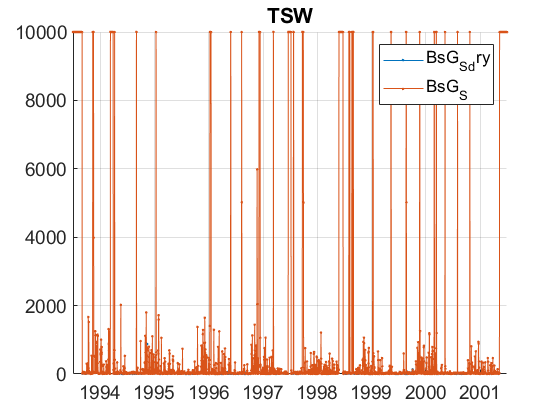

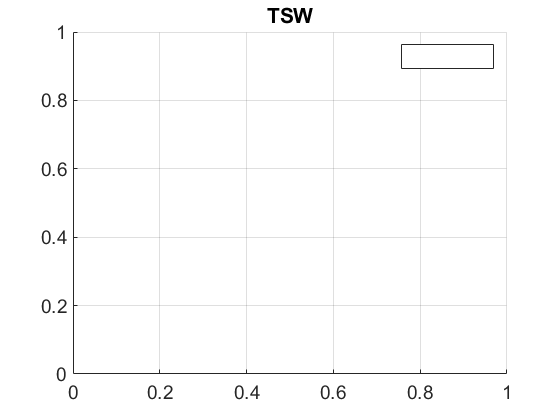

plotFigControl(TSW_rd,TSW_st.name);

% 1 size cut, 
% sc: ok, clear seasonal cycle, max in summer-autumn, some negatives

% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE3=[467;530;660]*ones(1,4);
% lambdaAE7=[370 470 520 590 660 880 950];
% TSW_cal=compute_exp_SSA(TSW_rd,lambdaSC, lambdaAE3);
% plotFigControl_cal(TSW_cal, TSW_st.name);

%Questions:
%problems:
% hole from end 2009 to April 2016

TSW_t=timetable(TSW_rd.Time);
% begin at the beginning of a year:1994
%end year: 2000--> 7y too short


